epsilon = 1e-6;
T = @(x) screw2TMat(x);

% Development of screw - Random or Specific Configuration
omega = rand(3, 1);
% omega = zeros(3, 1);
v = rand(3, 1);
% v = [0 0.5 0]';
xi = [omega; v];
disp("Screw:")

Screw:


disp(xi)

    0.9739
    0.2587
    0.3769
    0.6015
    0.5115
    0.6332




% Minimal energy configuration screw
xi_min = [2.2214 0 2.2214 -1.7524 0 1.7524]';

% Calculation of transformation matrix derivative at given screw.
tic
dT_dxi = screw2dT(xi_min);
% dT_dxi = screw2dT(xi);
toc

Elapsed time is 0.006098 seconds.



% Calculates the transformation matrix derivative numerically using the finite difference method
% and compares the analytical solution against it.
tic
for i = 1:6
    dx = zeros(6,1); 
    dx(i) = epsilon;
    T_plus = T(xi_min + dx);
    T_minus = T(xi_min - dx);
    % T_plus = T(xi + dx);
    % T_minus = T(xi - dx);
    dT_fd(:, :, i) = (T_plus - T_minus) / (2 * epsilon);
    
    dT_analytic = dT_dxi(:, :, i);
    
    % fprintf('Error in dT/dxi_%d: %e\n', i, norm(dT_fd(:, :, i) - dT_analytic));
end
toc

Elapsed time is 0.009173 seconds.



disp("Analytical Solution:")

Analytical Solution:


disp(dT_dxi)


(:,:,1) =

    0.4501    0.5000    0.0000    0.0000
   -0.5000   -0.0000    0.5000    0.3551
    0.0000   -0.5000   -0.4502   -0.7889
         0         0         0         0


(:,:,2) =

         0    0.4502    0.0000    0.3551
    0.4502         0    0.4502         0
   -0.0000    0.4502         0    0.3551
         0         0         0         0


(:,:,3) =

   -0.4502    0.5000    0.0000    0.7889
   -0.5000   -0.0000    0.5000    0.3551
    0.0000   -0.5000    0.4501   -0.0000
         0         0         0         0


(:,:,4) =

         0         0         0    0.5000
         0         0         0    0.4502
         0         0         0    0.5000
         0         0         0         0


(:,:,5) =

         0         0         0   -0.4502
         0         0         0    0.0000
         0         0         0    0.4502
         0         0         0         0


(:,:,6) =

         0         0         0    0.5000
         0         0         0   -0.4502
         0         0 

disp("Numerical Solution:")

Numerical Solution:


disp(dT_fd)


(:,:,1) =

    0.4501    0.5000    0.0000    0.0000
   -0.5000   -0.0000    0.5000    0.3551
    0.0000   -0.5000   -0.4502   -0.7889
         0         0         0         0


(:,:,2) =

         0    0.4502    0.0000    0.3551
    0.4502         0    0.4502         0
   -0.0000    0.4502         0    0.3551
         0         0         0         0


(:,:,3) =

   -0.4502    0.5000    0.0000    0.7889
   -0.5000   -0.0000    0.5000    0.3551
    0.0000   -0.5000    0.4501   -0.0000
         0         0         0         0


(:,:,4) =

         0         0         0    0.5000
         0         0         0    0.4502
         0         0         0    0.5000
         0         0         0         0


(:,:,5) =

         0         0         0   -0.4502
         0         0         0    0.0000
         0         0         0    0.4502
         0         0         0         0


(:,:,6) =

         0         0         0    0.5000
         0         0         0   -0.4502
         0         0 


% Comparison between Analytical and Numerical results
Analytical = dT_dxi;
Numerical  = dT_fd;
relError = norm(Analytical - Numerical, "fro") / norm(Analytical, "fro")

relError = 1.6433e-10

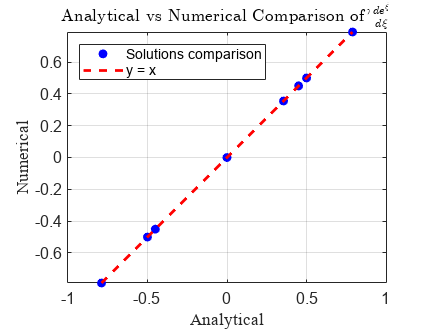


% Scatter Plot: Analytical vs Numerical
figure;
plot(Analytical(:), Numerical(:), 'bo', 'MarkerFaceColor','b');
hold on;
minVal = min([Analytical(:); Numerical(:)]);
maxVal = max([Analytical(:); Numerical(:)]);
plot([minVal, maxVal], [minVal, maxVal], 'r--', 'LineWidth', 2); % y = x line
xlabel('Analytical', "FontName", "Times New Roman");
ylabel('Numerical', "FontName", "Times New Roman");
title('Analytical vs Numerical Comparison of''$\frac{de^{\hat{\xi}}}{d\xi}$', "Interpreter","latex", "FontName", "Times New Roman", "FontWeight", "bold");
legend("Solutions comparison", "y = x", "Location", "northwest")
grid on;
axis equal;
set(gca, 'FontSize', 12);


% % Annotate with R^2 correlation
% R = corrcoef(Analytical(:), Numerical(:));
% text(minVal, maxVal, sprintf('R^2 = %.6f', R(1,2)^2), ...
%     'VerticalAlignment','bottom', 'FontSize', 12, 'BackgroundColor','w');